# PITCH RATE COMMAND

## Model Creation

A = [0,0,0,1;
    -32.17, -0.0226, -7.1835, -2.3823;
    0, -0.0005, -0.5261, 0.9270; % original mistake
    0, 0, -1.2333, -0.7914];
B = [0;
    0.0088;
    -0.0011;
    -0.0657];
C = [57.2958, 0, 0, 0;
    0, 1, 0, 0;
    0, 0, 57.2958, 0;
    0, 0, 0, 57.2958];
D = [0;
    0;
    0;
    0];

model_full = ss(A,B,C,D);
model_red = ss(A([3,4],[3,4]),B([3,4]),C([3,4],[3,4]),D([3,4]));

## Model Comparison

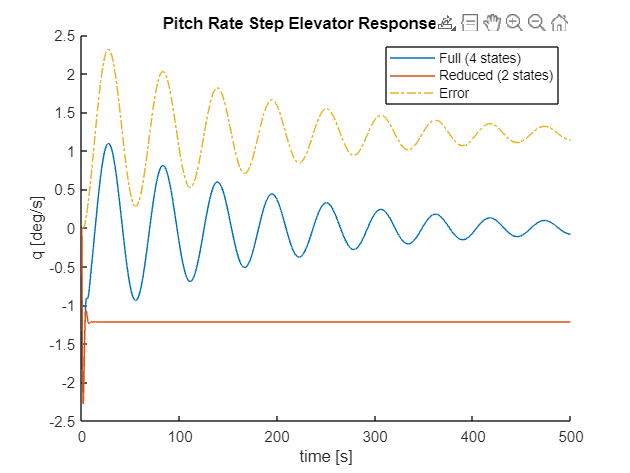

t_end = 500;
t = 0:0.1:t_end;
[y_full, t_full] = step(model_full, t);
[y_red, t_red] = step(model_red, t);
y_error = y_full(:, 4) - y_red(:, 2);

hold on
plot(t_full, y_full(:, 4))
plot(t_red, y_red(:, 2))
plot(t_red, y_error, "-.")
xlabel('time [s]')
ylabel('q [deg/s]')
title({'Pitch Rate Step Elevator Response (500s)'})
legend("Full (4 states)", "Reduced (2 states)", "Error")
xlim([0, t_end]);
ylim([-2.5, 2.5])

hold off

## Required Frequency and Damping

cont_mat = ctrb(A([3,4],[3,4]),B([3,4])); % check controllability
k = rank(cont_mat) % rank of 2 thus controllable

k = 2


omega = 3.2004;
T = 1/(0.75*omega);
zeta = 0.5;

num_pitch_req = [1 omega];
den_pitch_req = [1 omega omega^2];
pitch_tf_req = tf(num_pitch_req, den_pitch_req);
required_poles = pole(pitch_tf_req)

required_poles =   -1.6002 + 2.7716i
  -1.6002 - 2.7716i


## Pole Placement

a = tf(model_red); % first is alpha, second is q

K = place(model_red.A, model_red.B, required_poles)

K =  -126.2891  -26.5446



model_red_closed = feedback(model_red, K)

model_red_closed =
 
  A = 
           x1      x2
   x1  -8.486  -0.746
   x2  -476.6  -100.7
 
  B = 
            u1
   x1  -0.0011
   x2  -0.0657
 
  C = 
         x1    x2
   y1  57.3     0
   y2     0  57.3
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


## Check with Gust

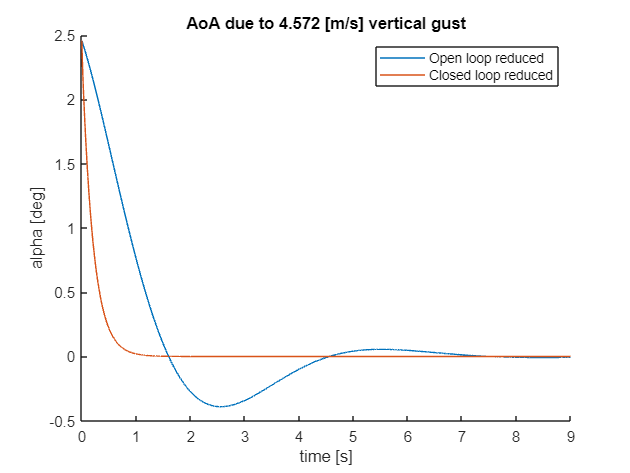

v_gust = 4.572;
t_end = 9;
alpha_gust = 4.572 / (350 * 0.3048);

x0 = [alpha_gust 0];
[yt, tt] = initial(model_red_closed, x0, 0:0.001:t_end);
[y, t] = initial(model_red, x0, 0:0.001:t_end);

clf
hold on
plot(t, y(:, 1));
plot(tt, yt(:, 1));
xlabel('time [s]')
ylabel('alpha [deg]')
title({'AoA due to 4.572 [m/s] vertical gust'})
legend("Open loop reduced", "Closed loop reduced")
xlim([0, t_end]);

## Lead-Lag Prefilter

s = tf('s');
[b, a] = ss2tf(model_red_closed.A, model_red_closed.B, model_red_closed.C, model_red_closed.D)

b =          0   -0.0630   -3.5394
         0   -3.7643   -1.9027


a =     1.0000  109.1998  499.0554


b = b(2, :);

T_old = b(2) / b(3)

T_old = 1.9784


old_zero = (1 + T_old * s);
new_zero = (1 + T * s);

H_prefilter = new_zero / old_zero

H_prefilter =
 
  0.4166 s + 1
  ------------
  1.978 s + 1
 
Continuous-time transfer function.
Model Properties



Kff = rscale(model_red_closed.A, model_red_closed.B, [0 1], 0, K);

model_compensated = minreal(Kff*H_prefilter*model_red_closed)

model_compensated =
 
  A = 
            x1       x2       x3
   x1   -8.486   -0.746   0.1049
   x2   -476.6   -100.7    6.263
   x3        0        0  -0.5055
 
  B = 
          u1
   x1  3.542
   x2  211.5
   x3     64
 
  C = 
         x1    x2    x3
   y1  57.3     0     0
   y2     0  57.3     0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



[b, a] = ss2tf(model_compensated.A, model_compensated.B, model_compensated.C, model_compensated.D)

b = 1.0e+04 *

         0    0.0203    1.1883    2.7353
         0    1.2120    3.5217    1.4704


a =     1.0000  109.7052  554.2505  252.2481


b = b(2, :);
T_current = b(2) / b(3)

T_current = 0.3441

## CAP / Gibson Criteria

V = 350 * 0.3048;

CAP_design = omega^2 / ((V/9.80665) * (1/T))

CAP_design = 0.3923

CAP_current = omega^2 / ((V/9.80665) * (1/T_current))

CAP_current = 0.3240

Cat A.

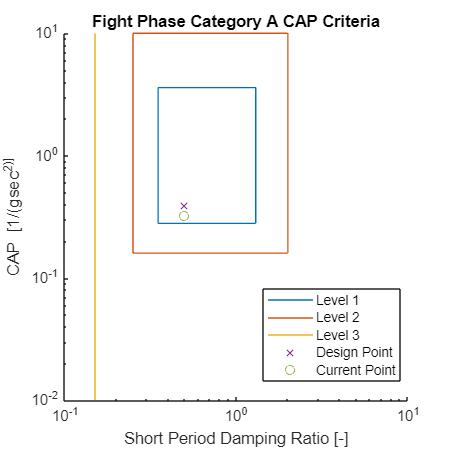

CAP_a_1 = [0.35 0.28; 1.3 0.28; 1.3 3.6; 0.35 3.6; 0.35 0.28];
CAP_a_2 = [0.25 0.16; 2 0.16; 2 10; 0.25 10; 0.25 0.16];
CAP_a_3 = [0.15 0.001; 0.15 10];

clf
hold on
set(gca,'xscale','log')
set(gca,'yscale','log')
plot(CAP_a_1(:,1), CAP_a_1(:,2))
plot(CAP_a_2(:,1), CAP_a_2(:,2))
plot(CAP_a_3(:,1), CAP_a_3(:,2))
plot(zeta, CAP_design, "x")
plot(zeta, CAP_current, "o")

xlabel('Short Period Damping Ratio [-]')
ylabel('CAP [1/(gsec^2)]')
title({'Fight Phase Category A CAP Criteria'})
set(gcf,'units','points','position',[0,0, 300, 300])
legend("Level 1", "Level 2", "Level 3", "Design Point", "Current Point")
ylim([0.01, 10])
xlim([0.1, 10])
legend("Position", [0.58544,0.15461,0.305,0.2025])
hold off

Cat B.

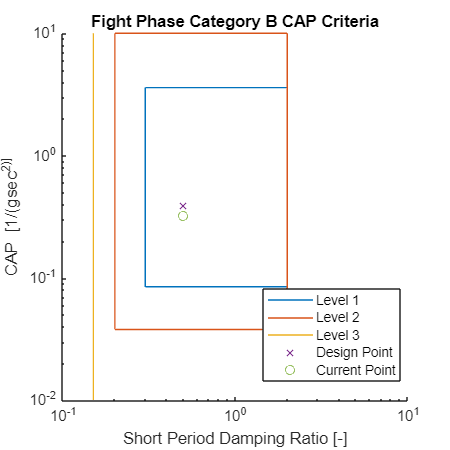

CAP_b_1 = [0.3 0.085; 2 0.085; 2 3.6; 0.3 3.6; 0.3 0.085];
CAP_b_2 = [0.2 0.038; 2 0.038; 2 10; 0.2 10; 0.2 0.038];
CAP_b_3 = [0.15 0.001; 0.15 10];

clf
hold on
set(gca,'xscale','log')
set(gca,'yscale','log')
plot(CAP_b_1(:,1), CAP_b_1(:,2))
plot(CAP_b_2(:,1), CAP_b_2(:,2))
plot(CAP_b_3(:,1), CAP_b_3(:,2))
plot(zeta, CAP_design, "x")
plot(zeta, CAP_current, "o")

xlabel('Short Period Damping Ratio [-]')
ylabel('CAP [1/(gsec^2)]')
title({'Fight Phase Category B CAP Criteria'})
set(gcf,'units','points','position',[0,0, 300, 300])
legend("Level 1", "Level 2", "Level 3", "Design Point", "Current Point")
ylim([0.01, 10])
xlim([0.1, 10])
legend("Position", [0.58544,0.15461,0.305,0.2025])
hold off

Cat C.

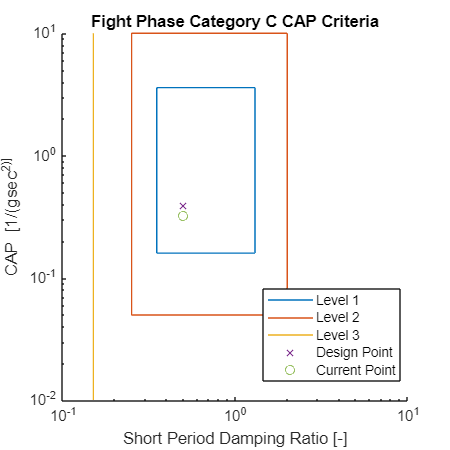

CAP_c_1 = [0.35 0.16; 1.3 0.16; 1.3 3.6; 0.35 3.6; 0.35 0.16];
CAP_c_2 = [0.25 0.05; 2 0.05; 2 10; 0.25 10; 0.25 0.05];
CAP_c_3 = [0.15 0.001; 0.15 10];

clf
hold on
set(gca,'xscale','log')
set(gca,'yscale','log')
plot(CAP_c_1(:,1), CAP_c_1(:,2))
plot(CAP_c_2(:,1), CAP_c_2(:,2))
plot(CAP_c_3(:,1), CAP_c_3(:,2))
plot(zeta, CAP_design, "x")
plot(zeta, CAP_current, "o")

xlabel('Short Period Damping Ratio [-]')
ylabel('CAP [1/(gsec^2)]')
title({'Fight Phase Category C CAP Criteria'})
set(gcf,'units','points','position',[0,0, 300, 300])
legend("Level 1", "Level 2", "Level 3", "Design Point", "Current Point")
ylim([0.01, 10])
xlim([0.1, 10])
legend("Position", [0.58544,0.15461,0.305,0.2025])
hold off

## Gibson Dropback Criteria

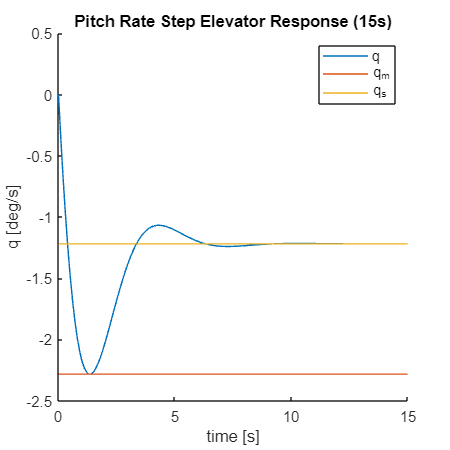

t_end = 15;
t = 0:0.1:t_end;
[y_red, t_red] = step(model_red, t);
qm = [0 -2.2848; t_end -2.2848];
qs = [0 -1.22; t_end -1.22];

clf
hold on
plot(t_red, y_red(:, 2))
plot(qm(:,1), qm(:,2))
plot(qs(:,1), qs(:,2))
xlabel('time [s]')
ylabel('q [deg/s]')
title({'Pitch Rate Step Elevator Response (15s)'})
legend("q", "q_m", "q_s")
xlim([0, t_end]);
ylim([-2.5, 0.5])

hold off

DB_design = T - 2*zeta / omega

DB_design = 0.1042

DB_current = T_current - 2*zeta / omega

DB_current = 0.0317



qm = -2.2848

qm = -2.2848

qs = -1.22

qs = -1.2200


qm_qs = qm/qs

qm_qs = 1.8728



clf
hold on
GIB_allowed_area = [0 1; 0.3 1; 0.06 3; 0 3; 0 1]

GIB_allowed_area =          0    1.0000
    0.3000    1.0000
    0.0600    3.0000
         0    3.0000
         0    1.0000


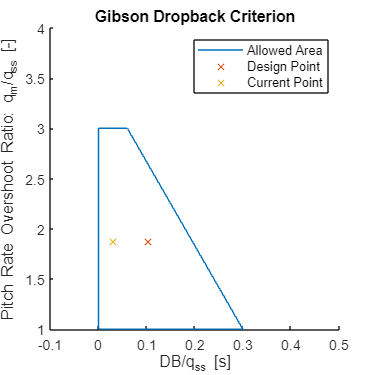

plot(GIB_allowed_area(:,1), GIB_allowed_area(:,2))
plot(DB_design, qm_qs, "x")
plot(DB_current, qm_qs, "x")

xlim([-0.1, 0.5]);
ylim([1, 4]);
xlabel('DB/q_ss [s]');
ylabel('Pitch Rate Overshoot Ratio: q_{m}/q_ss [-]');
title({'Gibson Dropback Criterion'})
legend("Allowed Area", "Design Point", "Current Point")
set(gcf,'units','points','position',[0,0, 250, 250])